# Cálculo

Este subcapítulo en el libro guía está algo desactualizado, por ende, se tomará la información de la documentación de **Symbolic Math Toolbox**. El enlace a esta documentación se encuentra al final del subcapítulo anterior (**sc3**).

## Diferenciación: función `diff`

La función `diff` permite difereciar (derivar) una expresión simbólica.

syms x y(x) t
eq = y(x) + diff(y(x)) - x == 0

$$eq = \frac{\partial }{\partial x}y\left(x\right)-x+y\left(x\right)=0$$

Se debe recordar que para nombrar variables sólo se puede utilizar letras, números y guión bajo. Por lo tanto, no es posible nombrar a una variable `f'`.

En cambio, si se desea diferenciar y evaluar a la vez se pueden utilizar las funciones `subs` y `vpa` de forma aninada.

subs(eq, x, t)

$$ans = \frac{\partial }{\partial t}y\left(t\right)-t+y\left(t\right)=0$$

Se hace hincapié una vez más (dentro de este capitulo) que para realizar cálculos con los resultados se deben convertir de simbólicos a numéricos.

Para derivar una constate se debe definirla previamente la constante como una expresión simbólica, caso contrario devolverá la fución `diff` una matriz vacía.

f(x) = exp(x) - sin(x) + x^5

$$f(x) = {\mathrm{e}}^{x}-\sin\left(x\right)+x^{5}$$

diff(f)

$$ans(x) = {\mathrm{e}}^{x}-\cos\left(x\right)+5\,x^{4}$$

### Derivada *n*-ésima (o de orden superior)

Existen dos formas de encontrar una derivada de orden superior: anidar varias funciones `diff` o ingresar un segundo argumento a esta.

Por ejemplo, utilizando la función $g$ definida anteriormente podemos encontrar su segunda derivada.

diff(f, 10)

$$ans(x) = {\mathrm{e}}^{x}+\sin\left(x\right)$$

### Derivadas parciales

Evidentemente también es posible determinar la derivada parcial de una función de dos o más variables.

syms y
g(x, y) = x*y^2 - sin(x)*y + y^3

$$g(x, y) = y^{3}+x\,y^{2}-\sin\left(x\right)\,y$$

Si no se especifica la variable respecto a la que derivar, MATLAB tomará la más cercana a **x** (porque **x** es la variable de derivación por defecto).

### Derivadas parciales de orden superior

Básicamente deberemos de especificar en la función `diff` la expresión, la variable de derivación y el orden de la derivada.

dgX = diff(g, x, 4)

$$dgX(x, y) = -y\,\sin\left(x\right)$$

## Integración: función `int`

La integración es el proceso contrario a la diferenciación. En realidad, por uno de los teoremas fundamentales del Cálculo se sabe que la derivada y la integral son funciones inversas.

Así pues, para encontrar la integral de una función dada se utiliza la función `int`.

**Nota:** En otros lenguajes de programación la función `int` define números enteros (**int**eger), sin embargo, en capítulos anteriores se estudiaron las formas en que MATLAB define los tipos de datos numéricos. Por ende, no se debe confundir la función `int` que sirve para integrar en MATLAB con la función `int` de otros lenguajes.

### Integral indefinida

Para integrales indefinidas MATLAB devuelve una única función, es decir, sin la constante de integración. Recordemos que la función obtenida mediante una integral es una familia de funciones en realidad.

Sea la siguiente integra indefinida


$$\int \cos(at+b)dt$$


podemos deteminarla utilizando MATLAB.

eq = x^2

$$eq = x^{2}$$

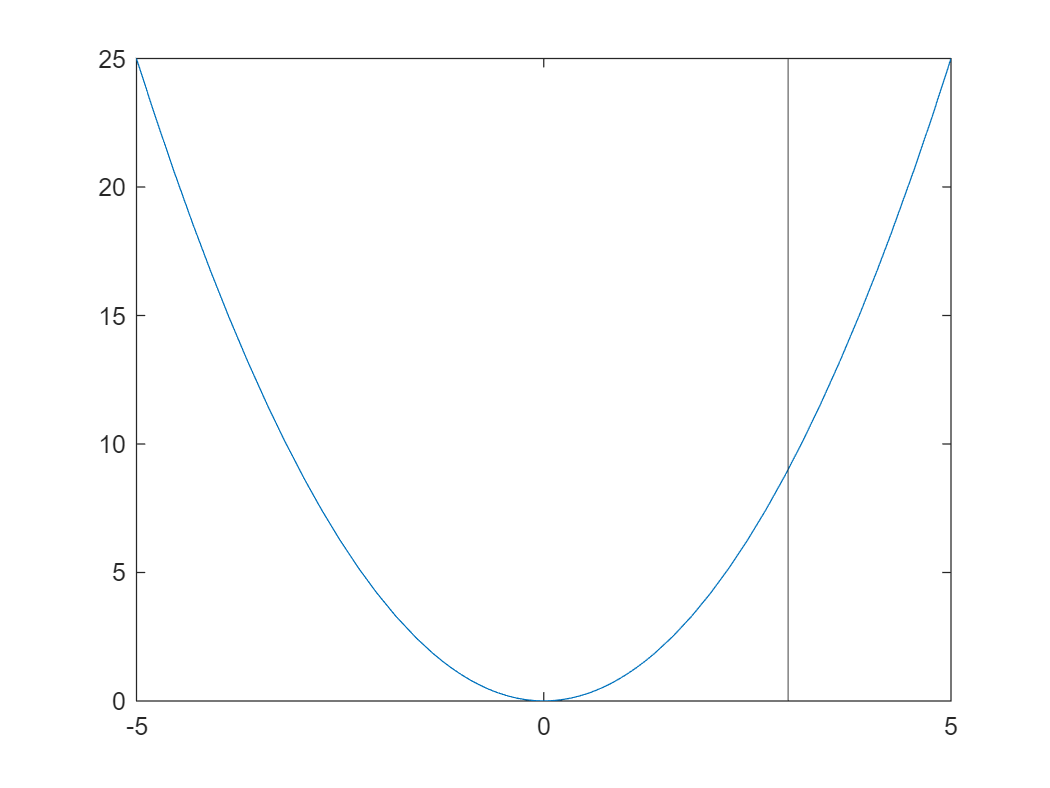

fplot(eq)
xline(3)

int(eq, x)

$$ans = \frac{x^{3}}{3}$$

h(x) = x^3/3 - 3

$$h(x) = \frac{x^{3}}{3}-3$$

diff(h)

$$ans(x) = x^{2}$$

Únicamente debemos recordar que en realidad no es una función, como ya se mencionó, si no una familia de funciones, pero MATLAB no añade la constante de integración al resultado.

**Nota:** Las mismas consideraciones respecto a la variable de diferenciación se aplican a la variable de integración.

### Integral definida

Sea la siguiente integral definida


$$\int_0 ^{\pi/2} \sin(2x)dx$$


podemos determinarla utilizando MATLAB.

int(sin(2*x), x, 0, pi/2)

$$ans = 1$$

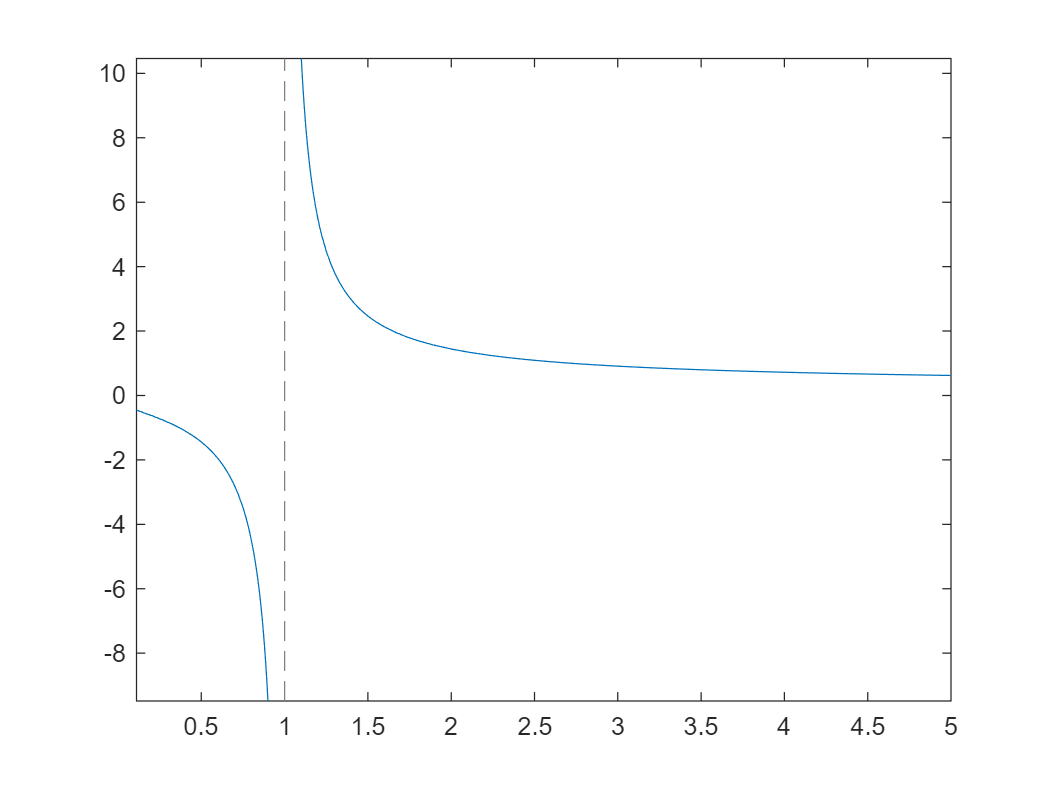

f(x) = 1/log(x);
fplot(f)

r(x) = int(f, x)

$$r(x) = \mathrm{logint}\left(x\right)$$

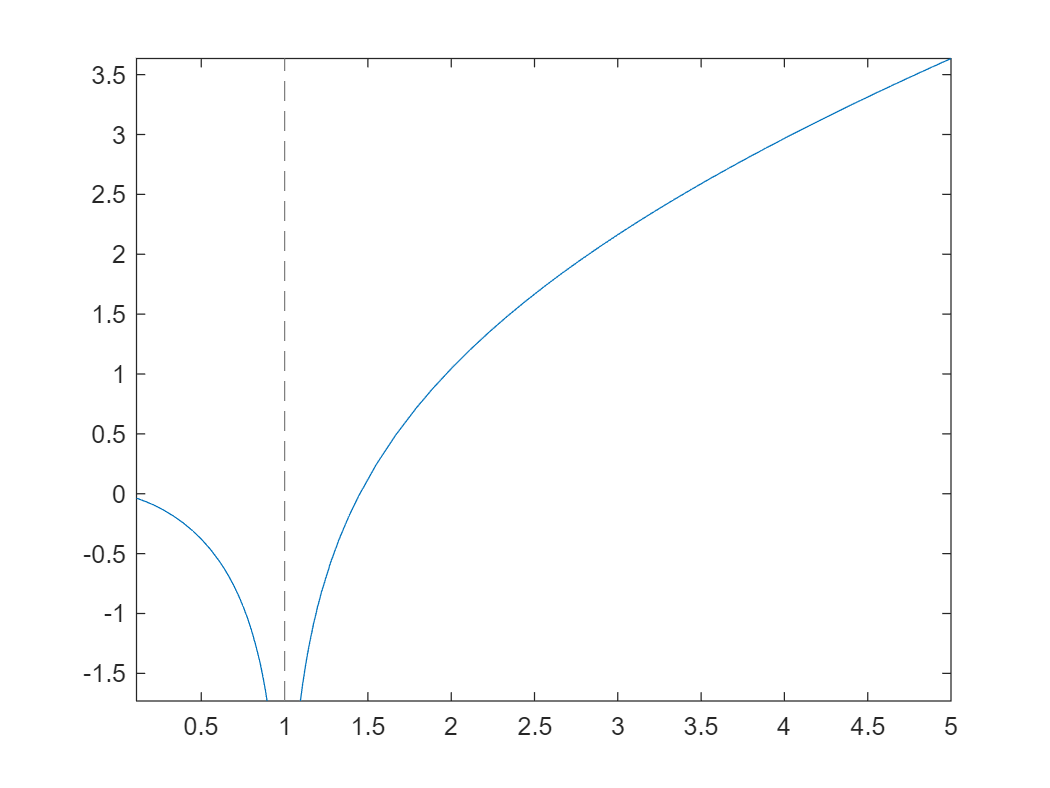

fplot(r)

### Aclaración acerca de las integrales en MATLAB

Se debe recordar que no toda función es integrable, o al menos no tiene una versión corta de sí. Algunas antiderivadas suelen ser extensas. En estos casos es posible que MATLAB no pueda determinarlas o devuelva una función que tenga la expresión `erf` que signica función errónea (*error function*).

Además, también existen integrales impropias que tienen un tratamiento especial. Por ende, a diferencia del cálculo diferencial, el cálculo integral puede ser limitado en MATLAB.

# Ecuaciones diferenciales

El tema de ecuaciones diferenciales es demasiado amplio para cubrirlo en este repositorio, siquiera para hacer un resumen. Por ende, aquí se incluirá lo exclusivamente fundametal de las ecuaciones diferenciales.

Para conocer todo lo que se puede realizar con MATLAB sobre este tema se recomienda sobremanera revisar la documentación.

## Ecuación diferencial ordinaria de primer orden: función `dsolve`

Lo primero que se debe hacer es definir la ecuación diferencial. Una vez definida la ecuación se puede utilizar la función `dsolve` tanto para una solución sin condiciones de frontera como con ellas.

### Sin condiciones de frontera

Sea la ecuación diferencial


$$\frac{dy}{dt}=ty$$


podemos solucionarla utilizando MATLAB.

syms t y(t)
eq = diff(y) == t*y

$$eq(t) = \frac{\partial }{\partial t}y\left(t\right)=t\,y\left(t\right)$$

dsolve(eq)

$$ans = C_{1}\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$

### Con condiciones de frontera

Además de definir la ecuación diferencial se definen las condiciones de frontera.

Sea la condición de frontera de la anterior ecuación diferencial


$$y(0)=2$$


entonces tenemos:

dsolve(eq, y(0) == 2)

$$ans = 2\,{\mathrm{e}}^{\frac{t^{2}}{2}}$$